# k-Nearest Neighbors example with Fisher Iris Dataset

This script shows the k-nearest neighbors for a new sample point

### Loads Fisher Iris dataset and selects petal lengths and widths

load fisheriris

X = meas(:,4);
Y = meas(:,3);
X_new = 1.5; Y_new = 5.3;

% select k for k-nearest neighbors
k = 11;9

ans = 9


Mdl = fitcknn([X,Y],species,'NumNeighbors',k);
[Idx,D] = knnsearch([X,Y],[X_new,Y_new],'K',k);

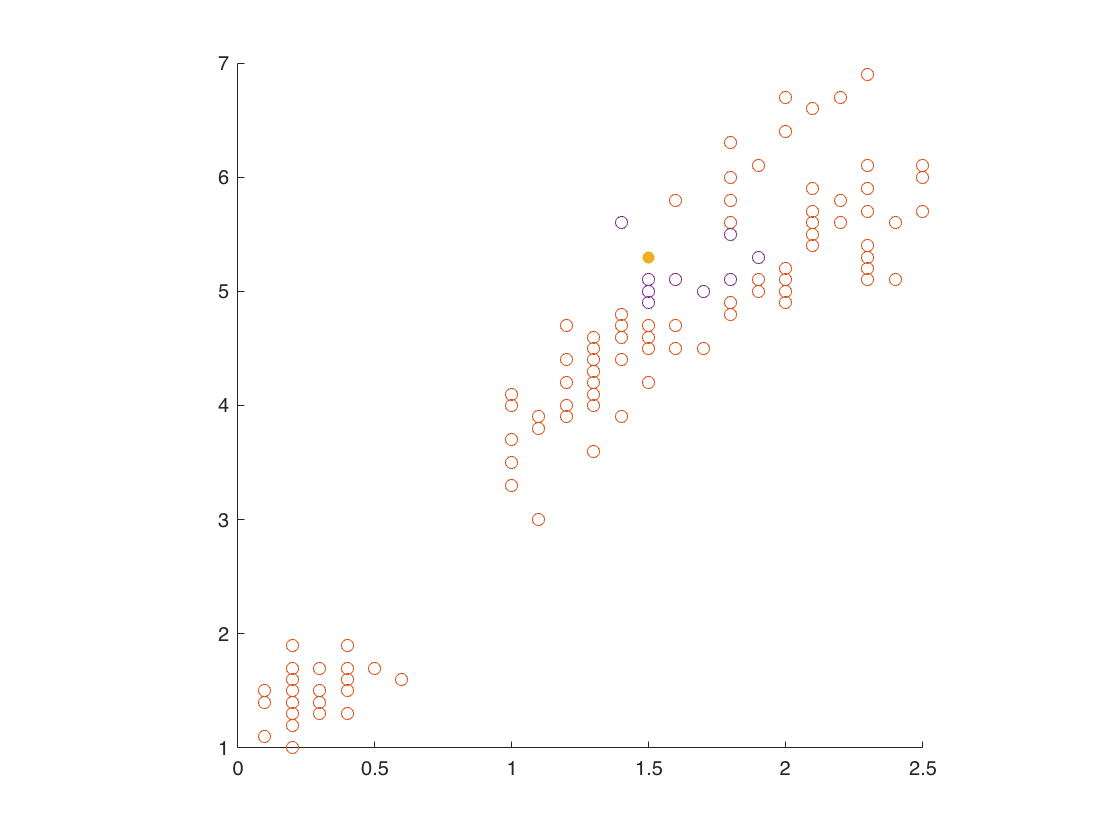

scatter(X,Y)
axis square
hold on
scatter(X_new,Y_new,'filled')
scatter(X(Idx),Y(Idx))


closest = [X(Idx),Y(Idx),D'];